# Robust Principal Component Analysis (PCA)

#### Background 

In **classic PCA**, outliers distort the principal components — you can't tell what is structure and what is noise.

In **Robust PCA**, outliers are found and the covariance (correlation) is computed without the outlying units. Robust PCA is designed with outlier resilience in mind.

#### Example: robust PCA for the citiesItaly dataset

load citiesItaly.mat
disp(citiesItaly.Properties.Description)

The citiesItaly dataset contains 107 records for the 107 provinces of Italy for seven indicators concerning the quality of life: The 7 variables are:
addedval = added value per capita
depost = amount of bank deposits per inhabitant
unemploy = unemployment rate
export = percentage of export divided by GNP of the province
bankrup = percentage of bankruptcy declarations on active companies
billsover = bills overdue indicator (percentage of bills protested on bills issued)
The data come from the Italian financial newspaper Il Sole 24 Ore, which every year produces the quality of life ranking of the Italian provinces.


Function [pcaFS](http://rosa.unipr.it/FSDA/pcaFS.html) is called with option `robust` set to `true`

Initial correlation matrix
                  addedval    depos    pensions    unemploy    export    bankrup    billsoverd
                  ________    _____    ________    ________    ______    _______    __________

    addedval        1.00       0.91      0.73       -0.82       0.59      -0.04       -0.49   
    depos           0.91       1.00      0.70       -0.79       0.53      -0.03       -0.49   
    pensions        0.73       0.70      1.00       -0.52       0.35       0.24       -0.46   
    unemploy       -0.82      -0.79     -0.52        1.00      -0.61       0.18        0.43   
    export          0.59       0.53      0.35       -0.61       1.00       0.07

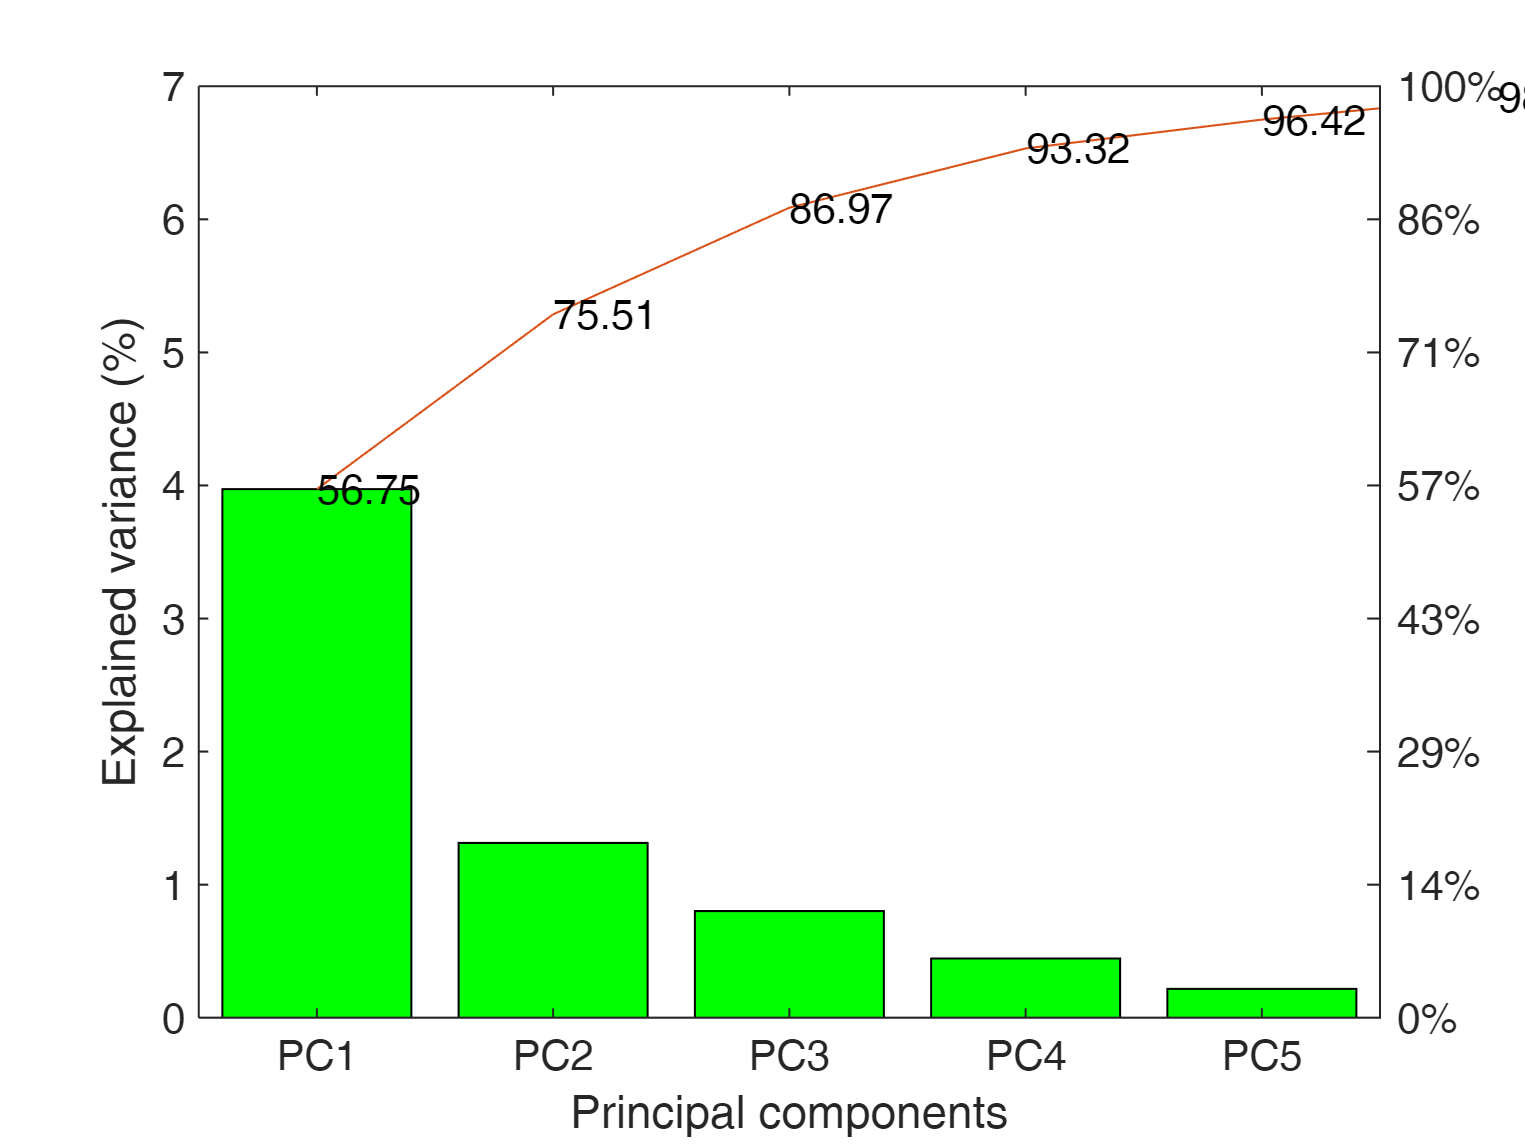

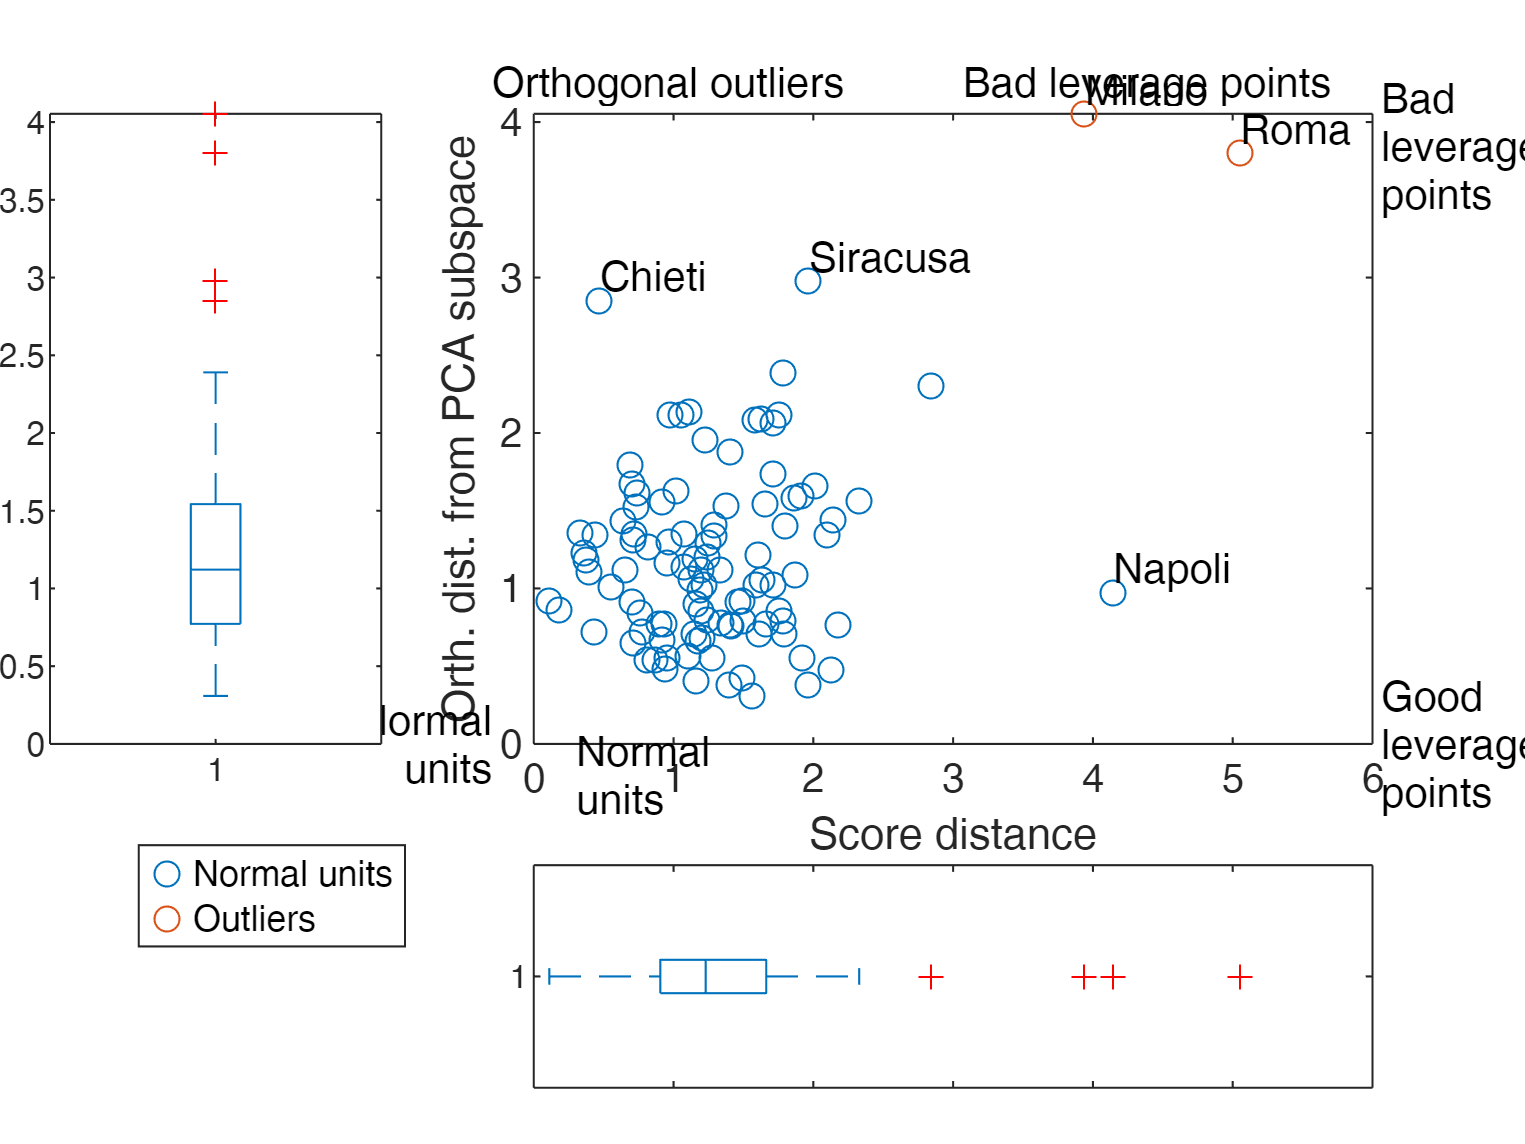

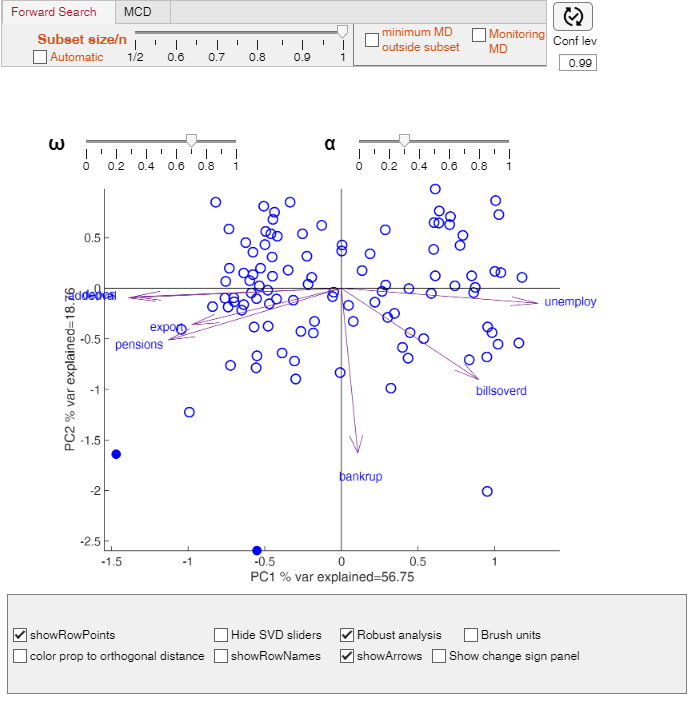

ans = struct with fields:
            Rtable: [7×7 table]
         explained: [7×3 double]
        explainedT: [7×3 table]
             coeff: [7×2 double]
            coeffT: [7×2 table]
          loadings: [7×2 double]
         loadingsT: [7×2 table]
     communalities: [7×3 double]
    communalitiesT: [7×3 table]
             score: [103×2 double]
            scoreT: [103×2 table]
          orthDist: [103×1 double]
         scoreDist: [103×1 double]
             class: 'pcaFS'


pcaFS(citiesItaly,'robust',true)

In this example two towns (Milano and Roma) are detected as outliers and are shown with filled blue circles inside the biplot.

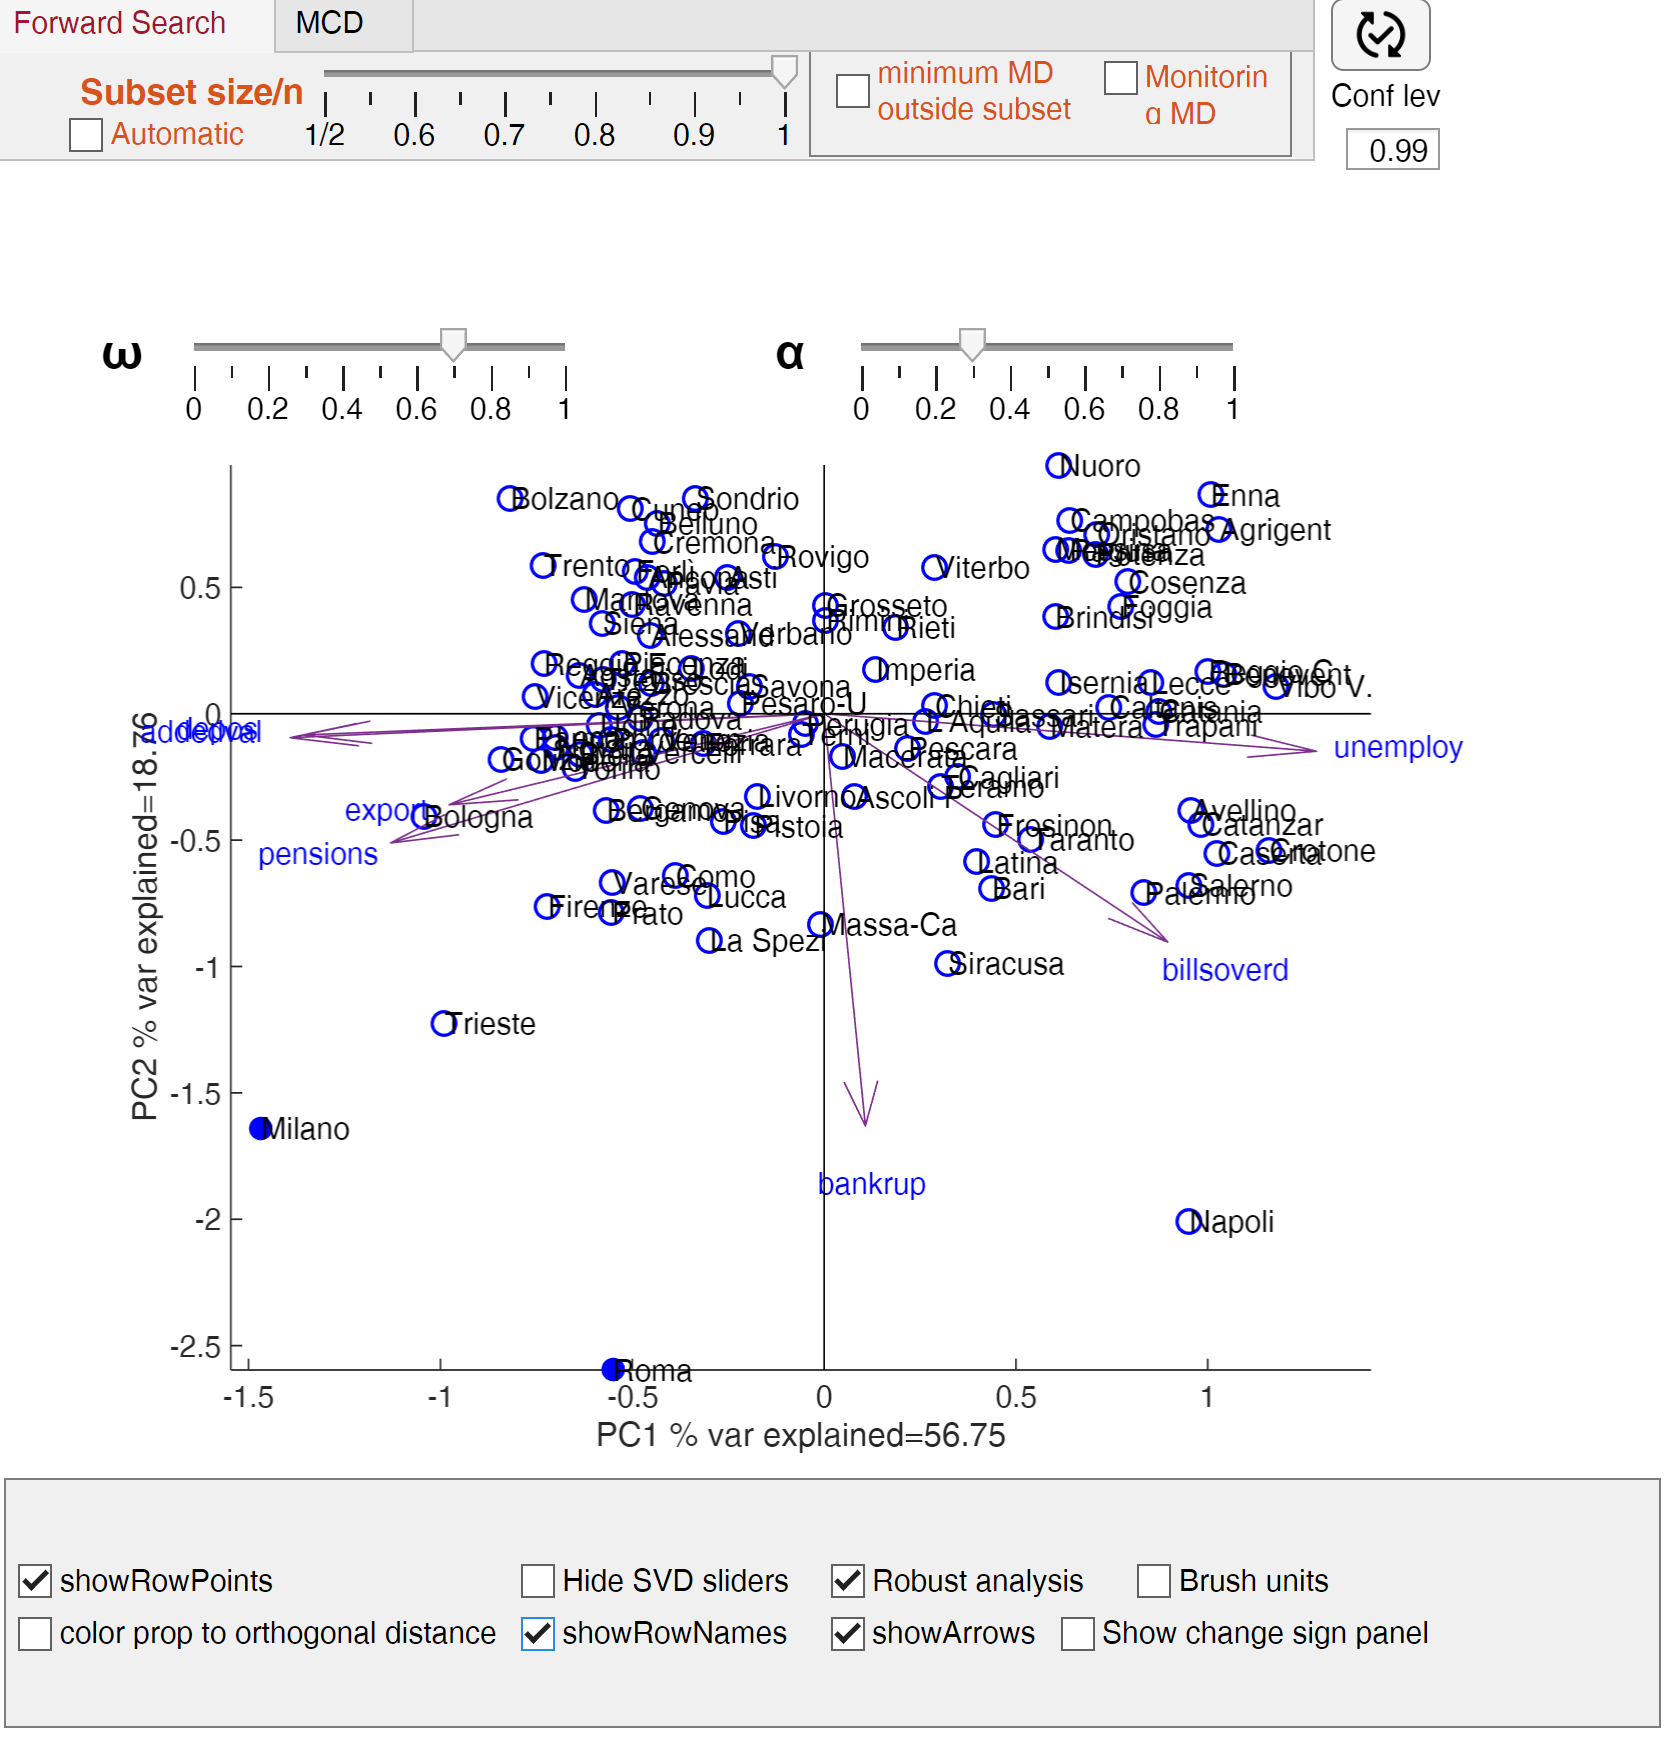

In the top part of the GUI of the biplot APP it is possible to choose as robust estimator FS (forward search), using a different subset size or the MCD, using a different value of breakdown point (Atkinson et al. 2025).

For example, if you choose a value of breakdown point equal to 0.5, here is the biplot which is automatically shown.

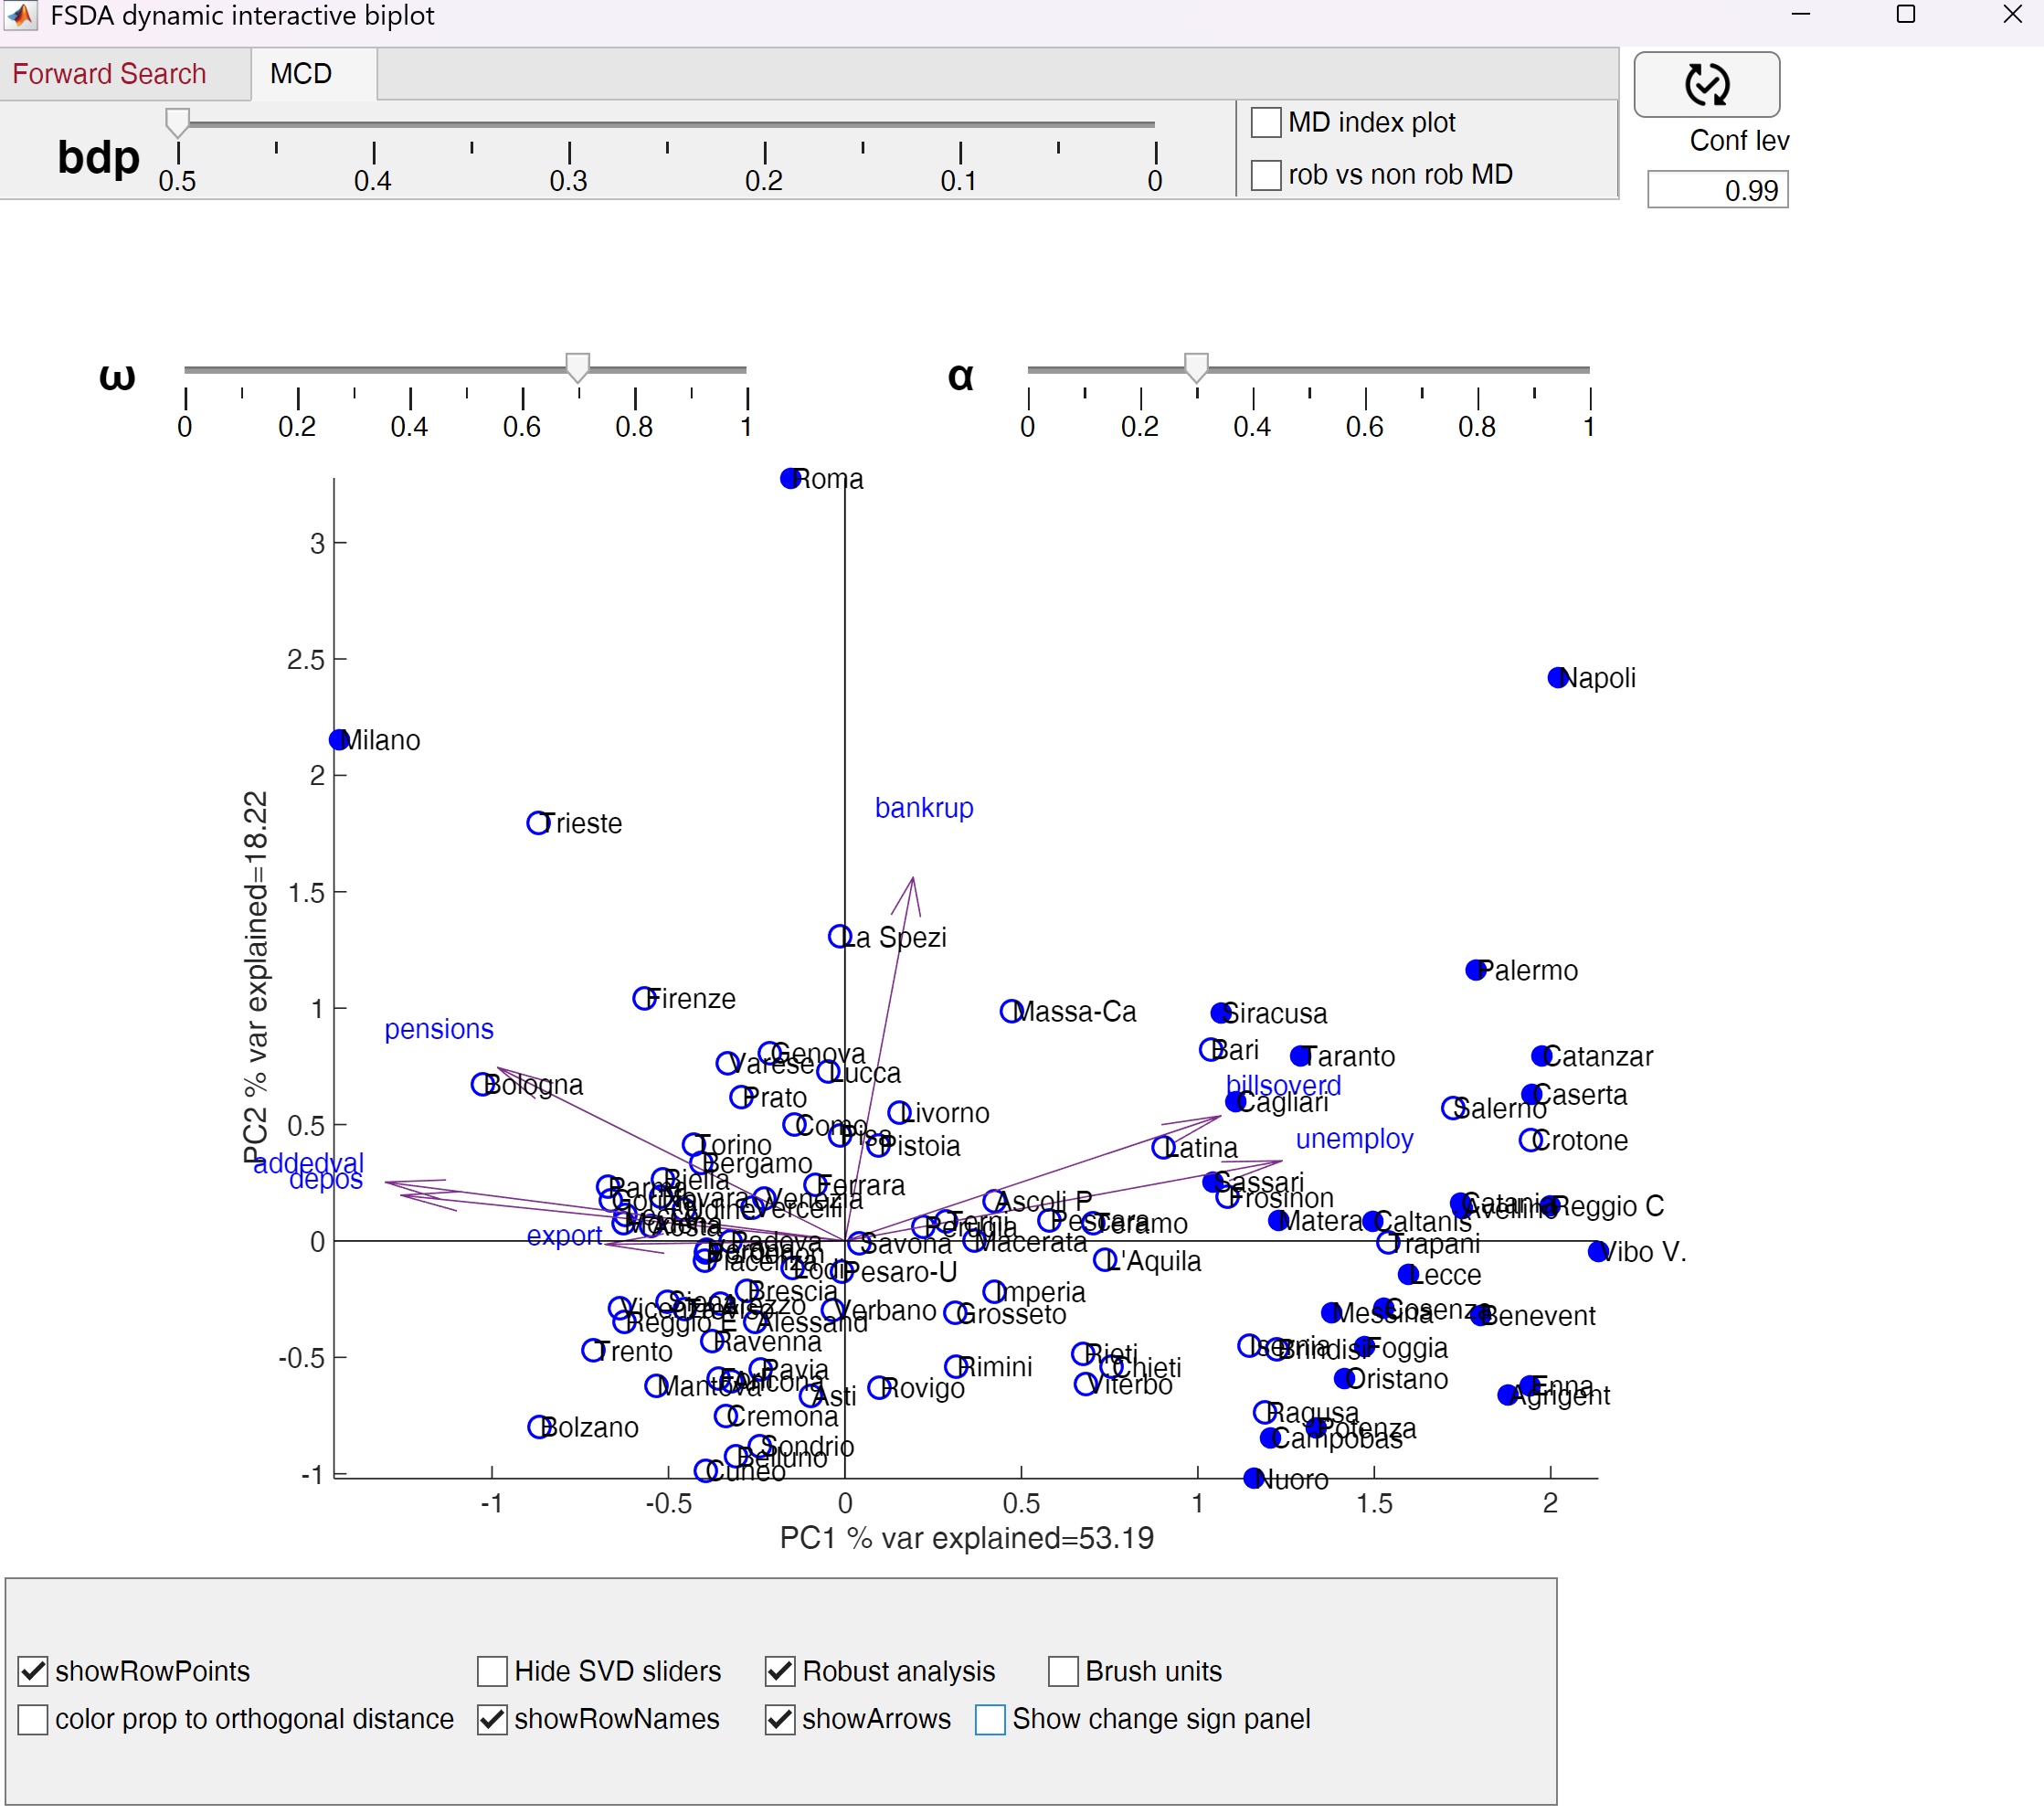

Most of the units which are located in southern Italy are declared as outliers (see also the outlier map plot).

In the literature based on MCD it is common to plot:

1) the robust vs non robust Mahalanobis distances 

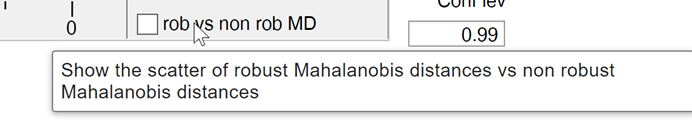

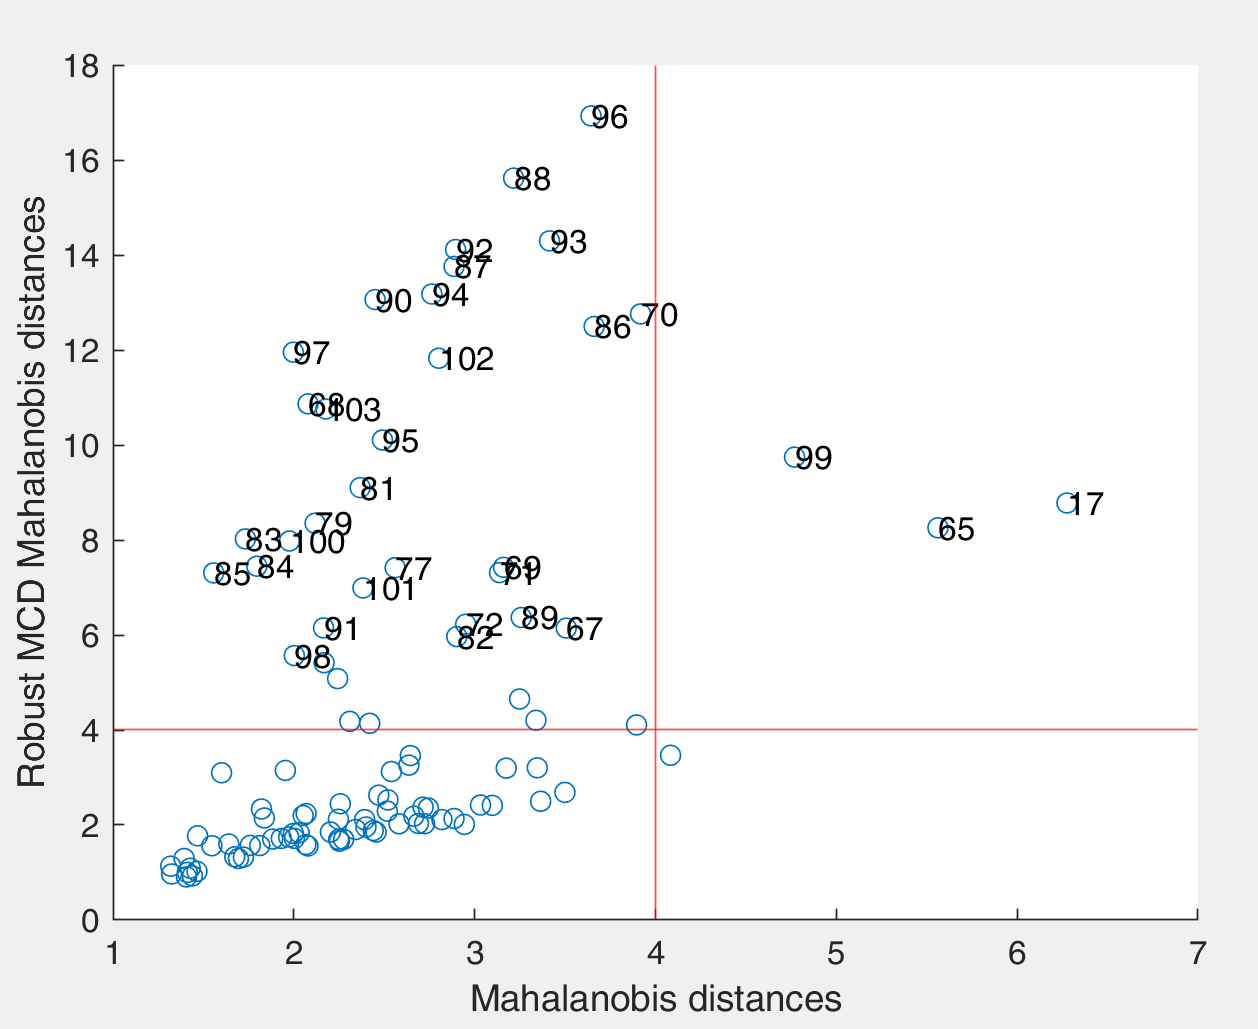

2) the index plot of robust (squared) Mahalanobis distances

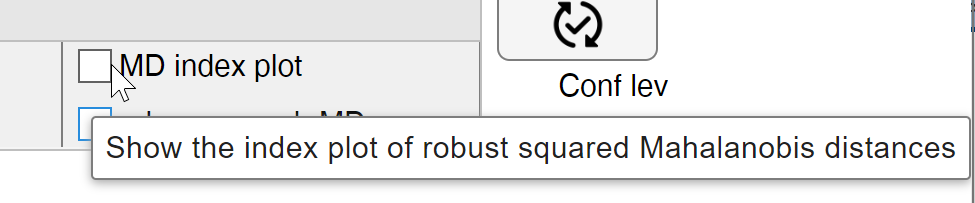

Figure below shows that the units with largest robust Mahalanobis distances (MD) are associated with the provinces which have the last positions (given that the ordering of the units goes from north to south) these provinces are mainly referred to towns located in southern  Italy.

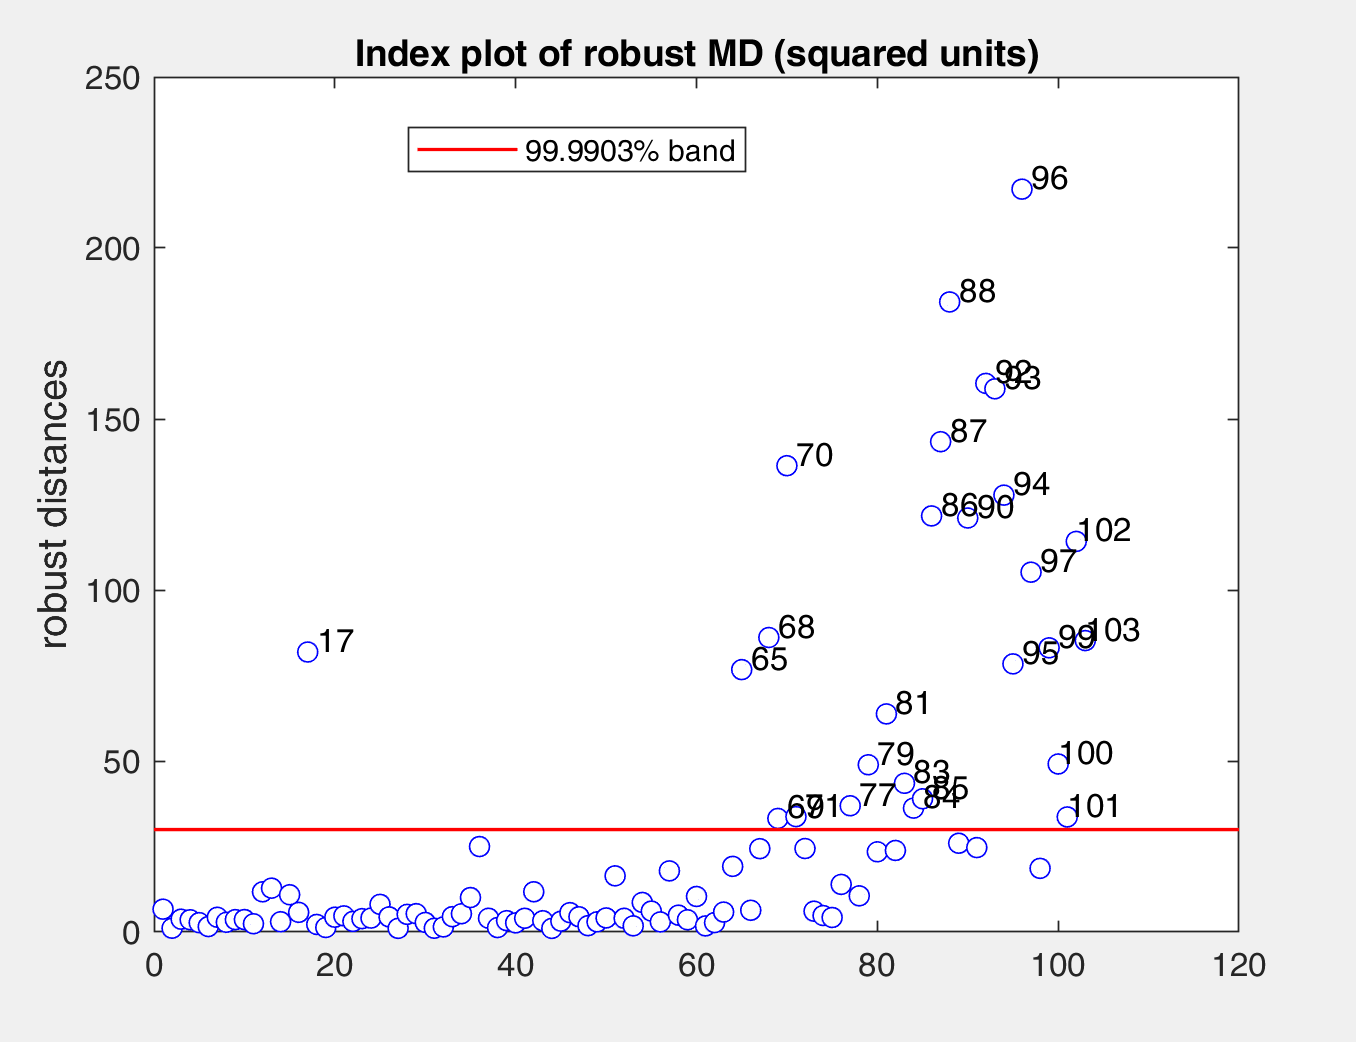

In the literature based on FS it is common to plot:

1) the minimum distance outside subset in order to automatically detect the outlying units  (see Riani et al. 2009). 

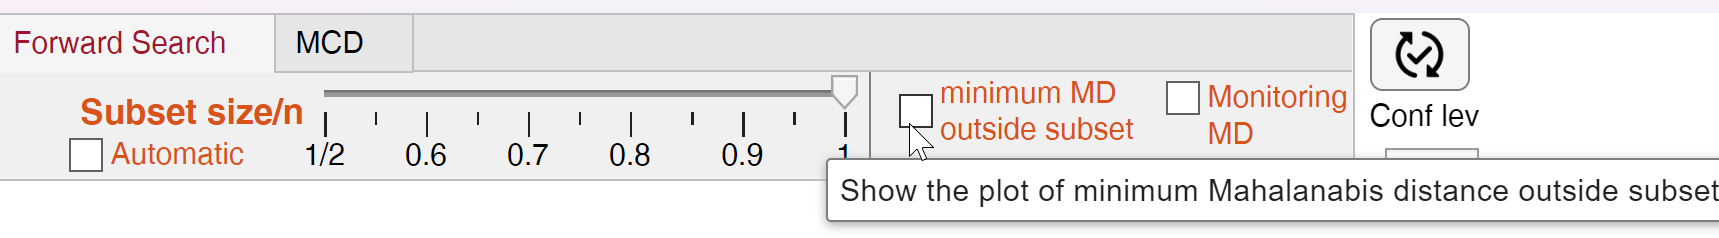

In this case it is immediate to see that the last two units which enter the search (Rome and Milan) have a distance which is very far from that of the other units.

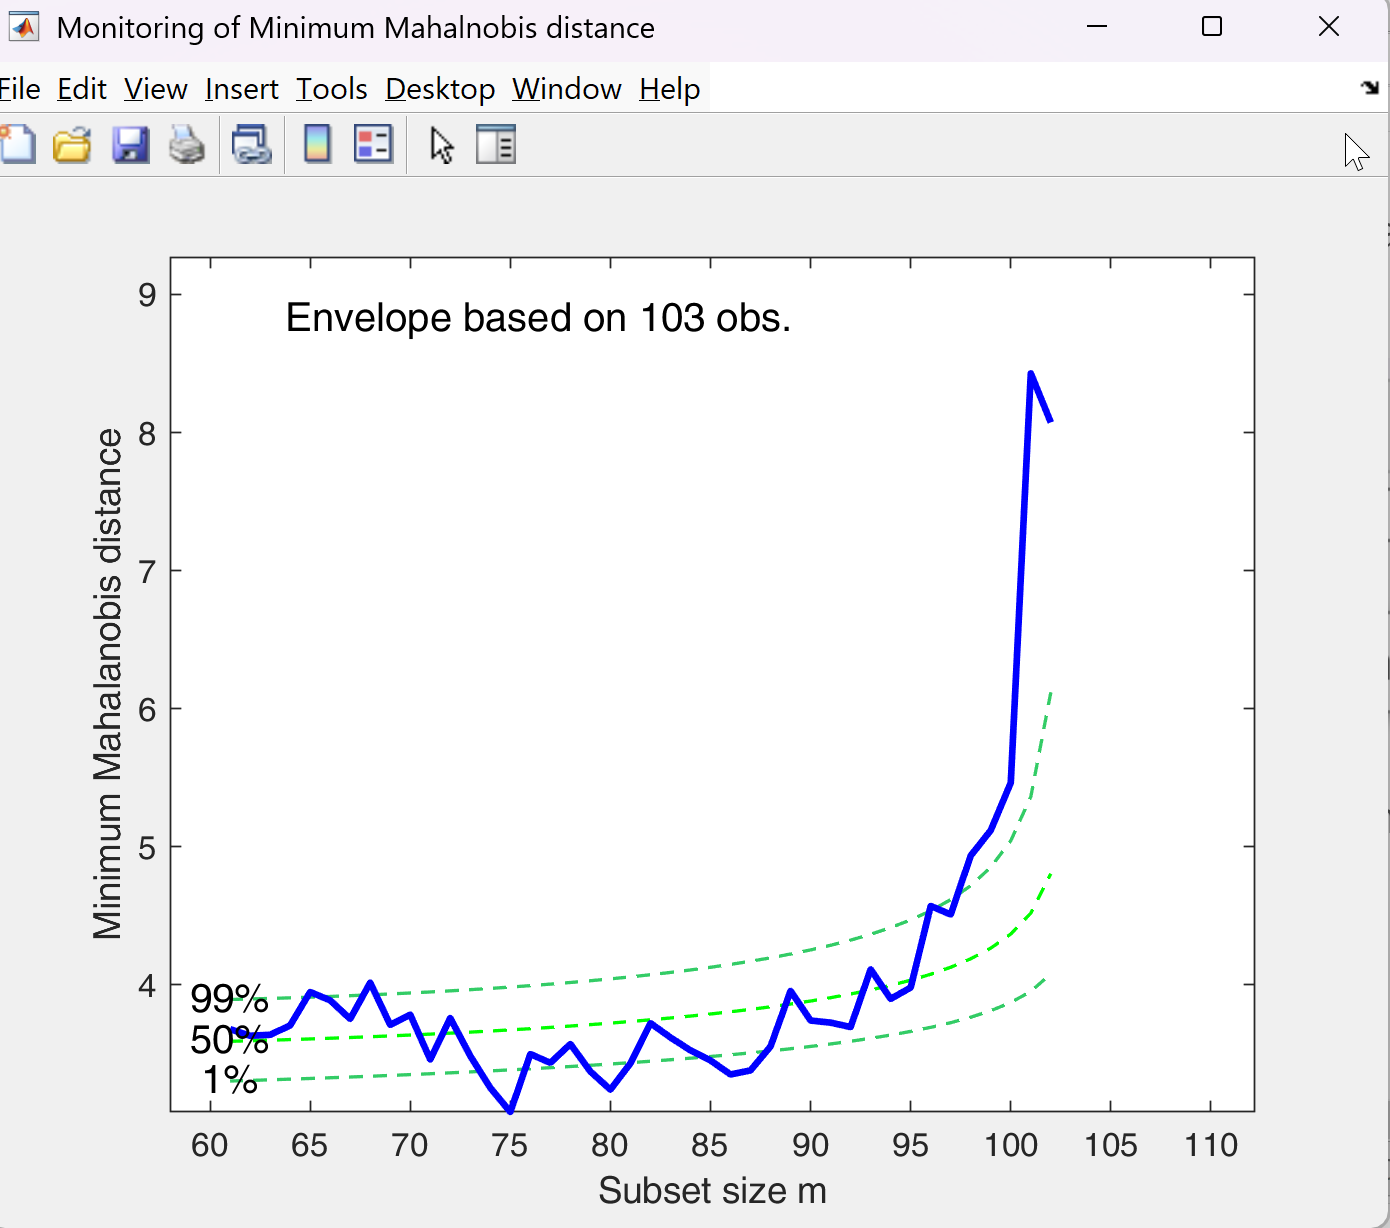

Notice also that the values of minimum MD around subset size m around 64-68 show values which are persistenly above the upper envelope and then are below the lower band. This is indeed an indication of the presence of two groups in the data.

2) Another plot which is common in the literature of FS is the one of monitoring MD as a function of the subset size.

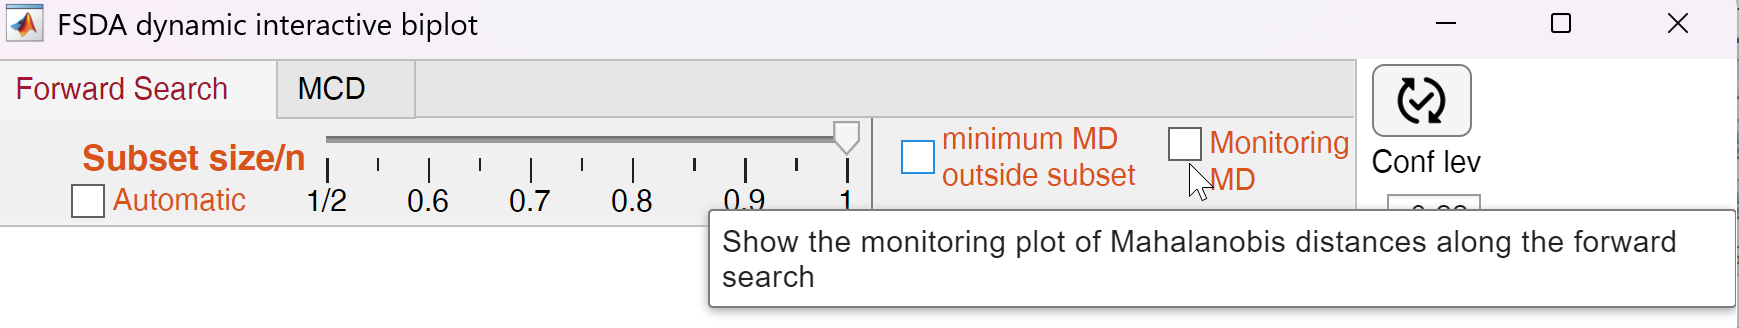

This plot shows that beyond the two outlying units (Rome and Milan) there is a bunch of units (associated with the provinces which are in  southern Italy) whose MD decreases as the subset size increases 

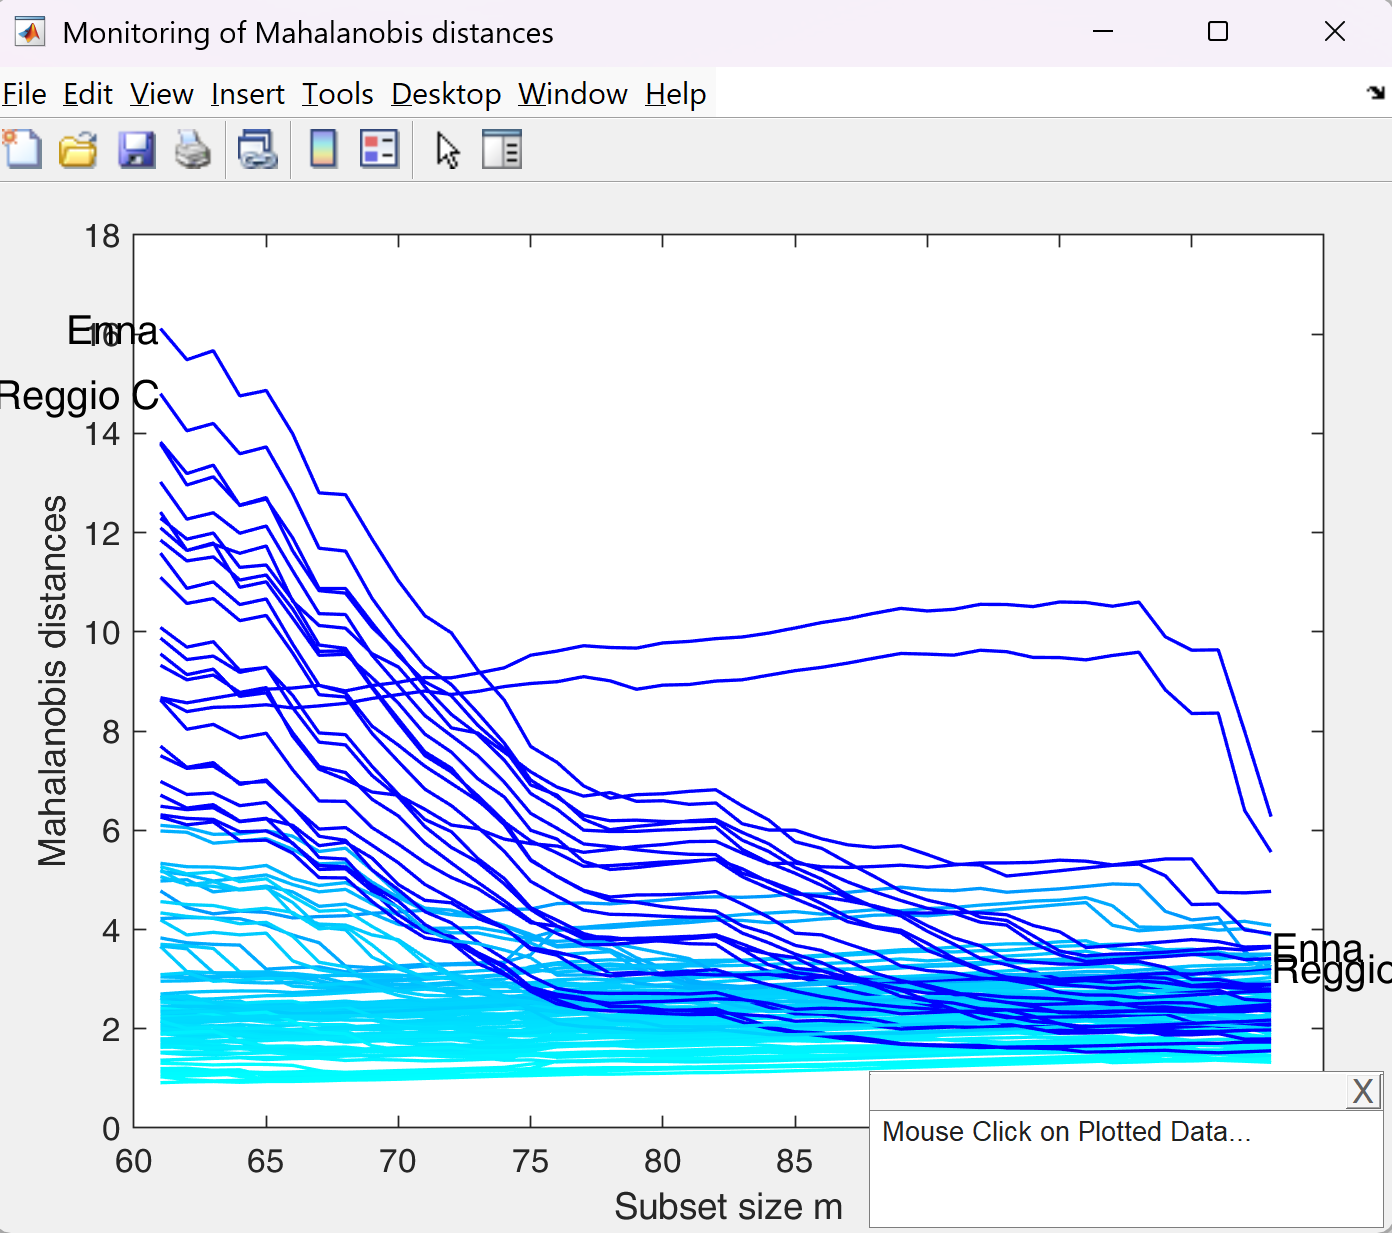

Finally, the button `UPDATE` on the top right part of the GUI (see screenshot below).

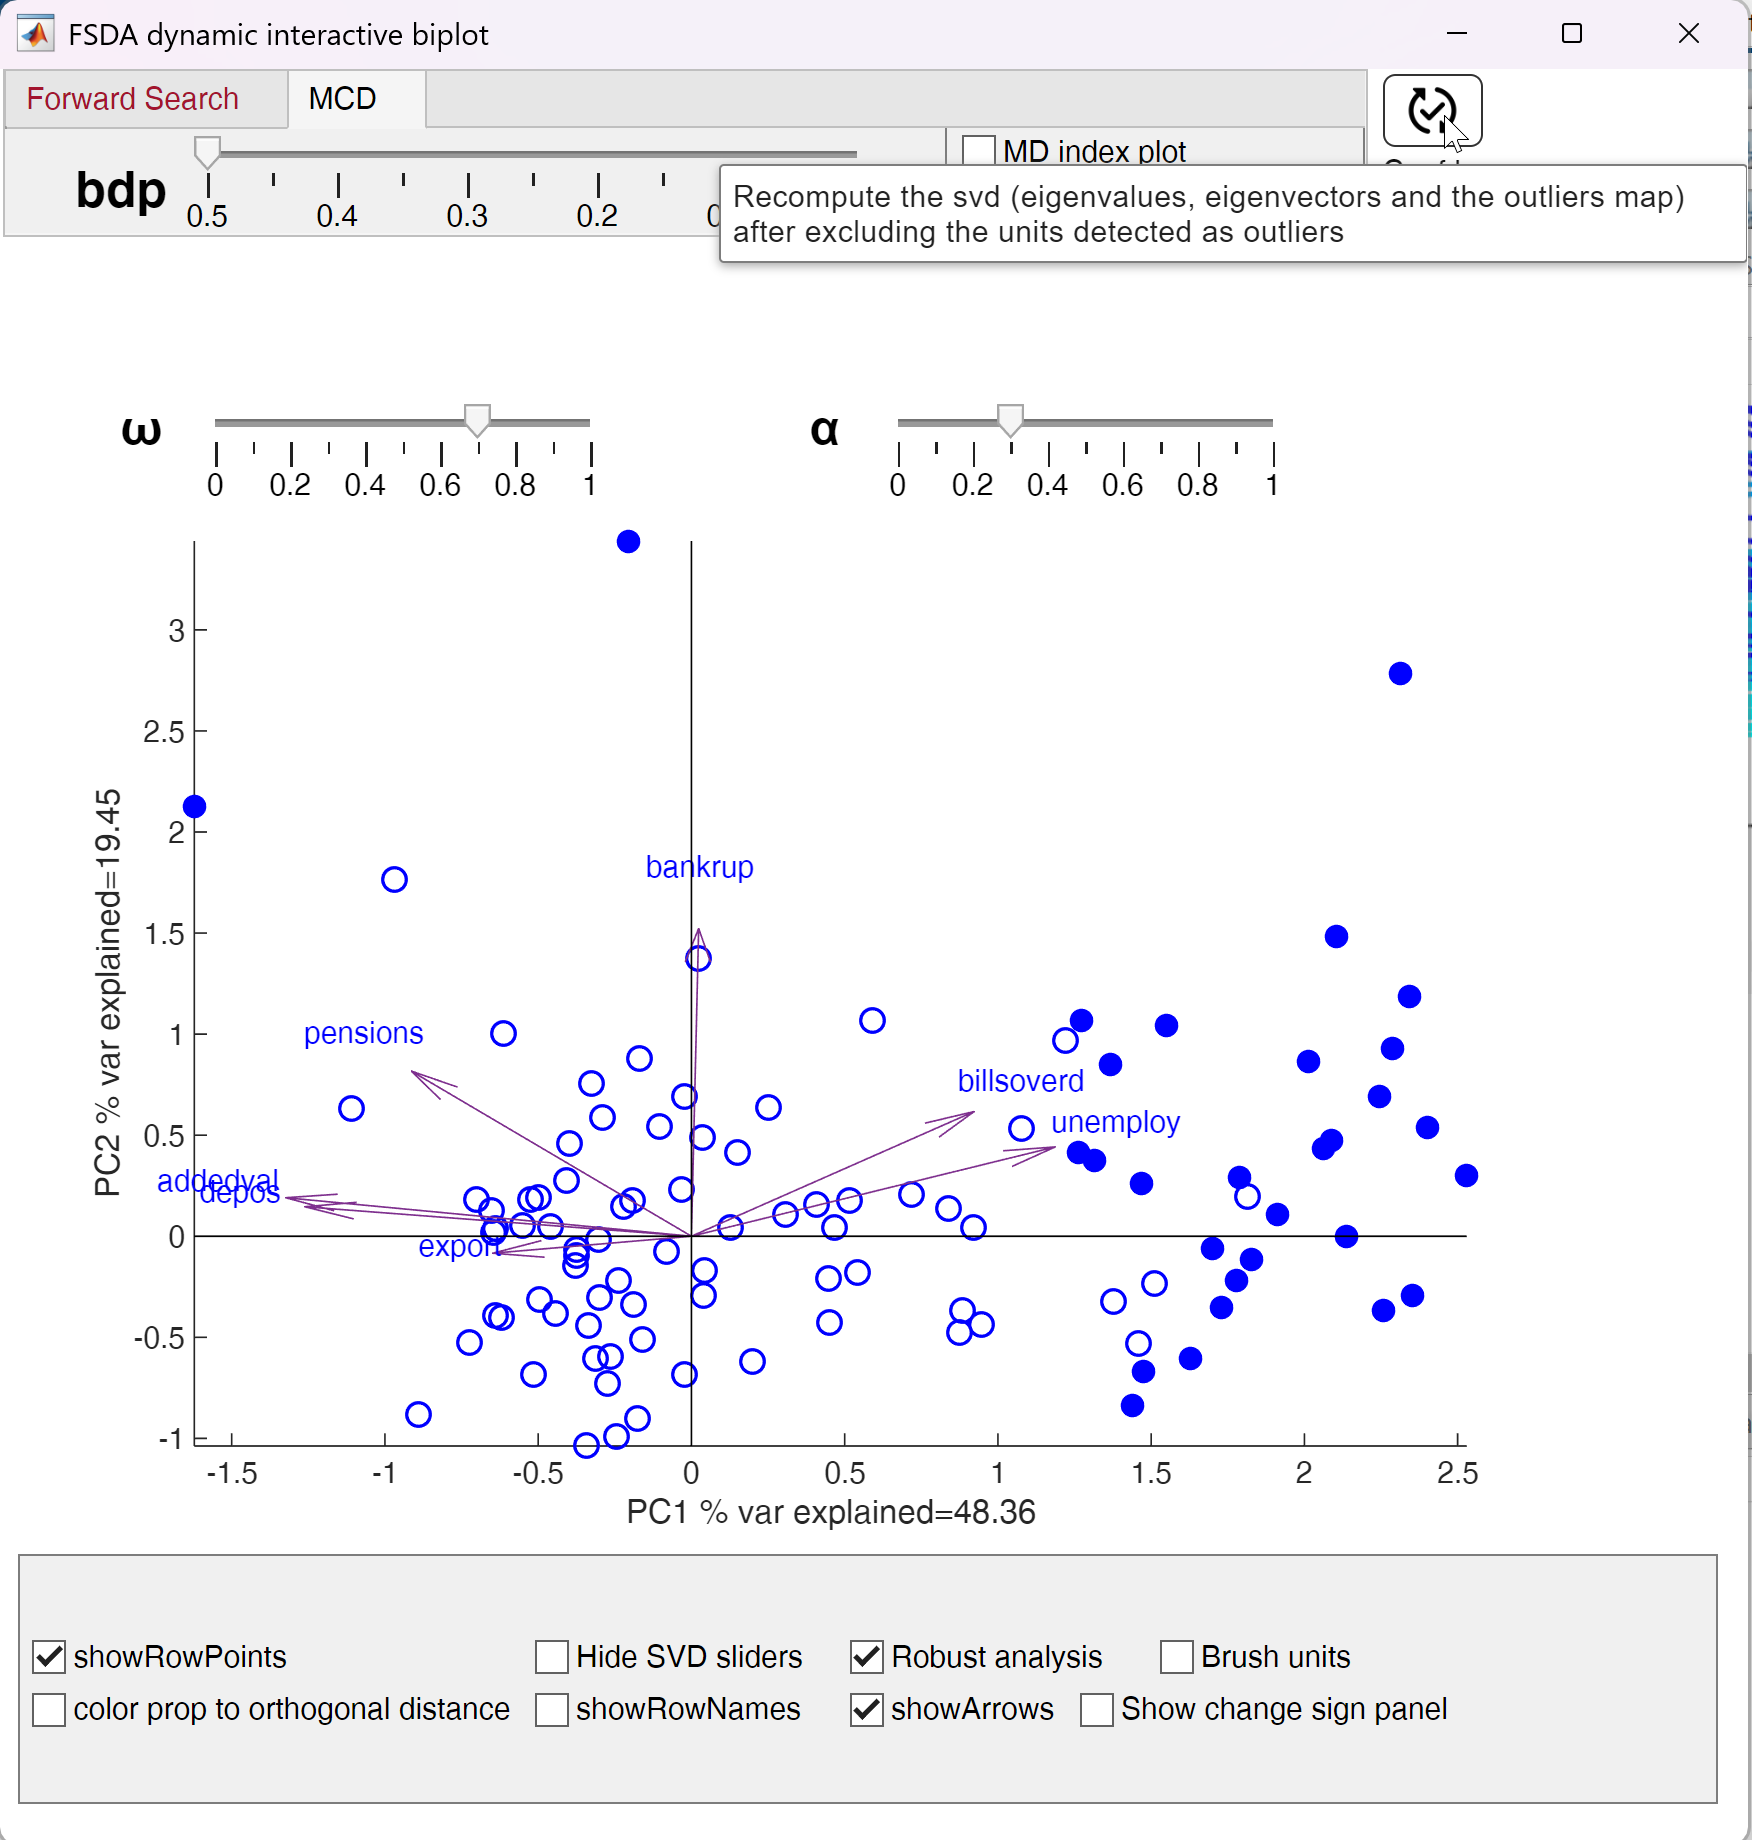

Clicking on this button enables us to have the new SVD and all the other plots with the units detected as outliers excluded from the correlation matrix and the associated SVD.

For example, if MCD with bdp=0.5 had been selected, these are the new plots which appear after clicking ont the UPDATE button.

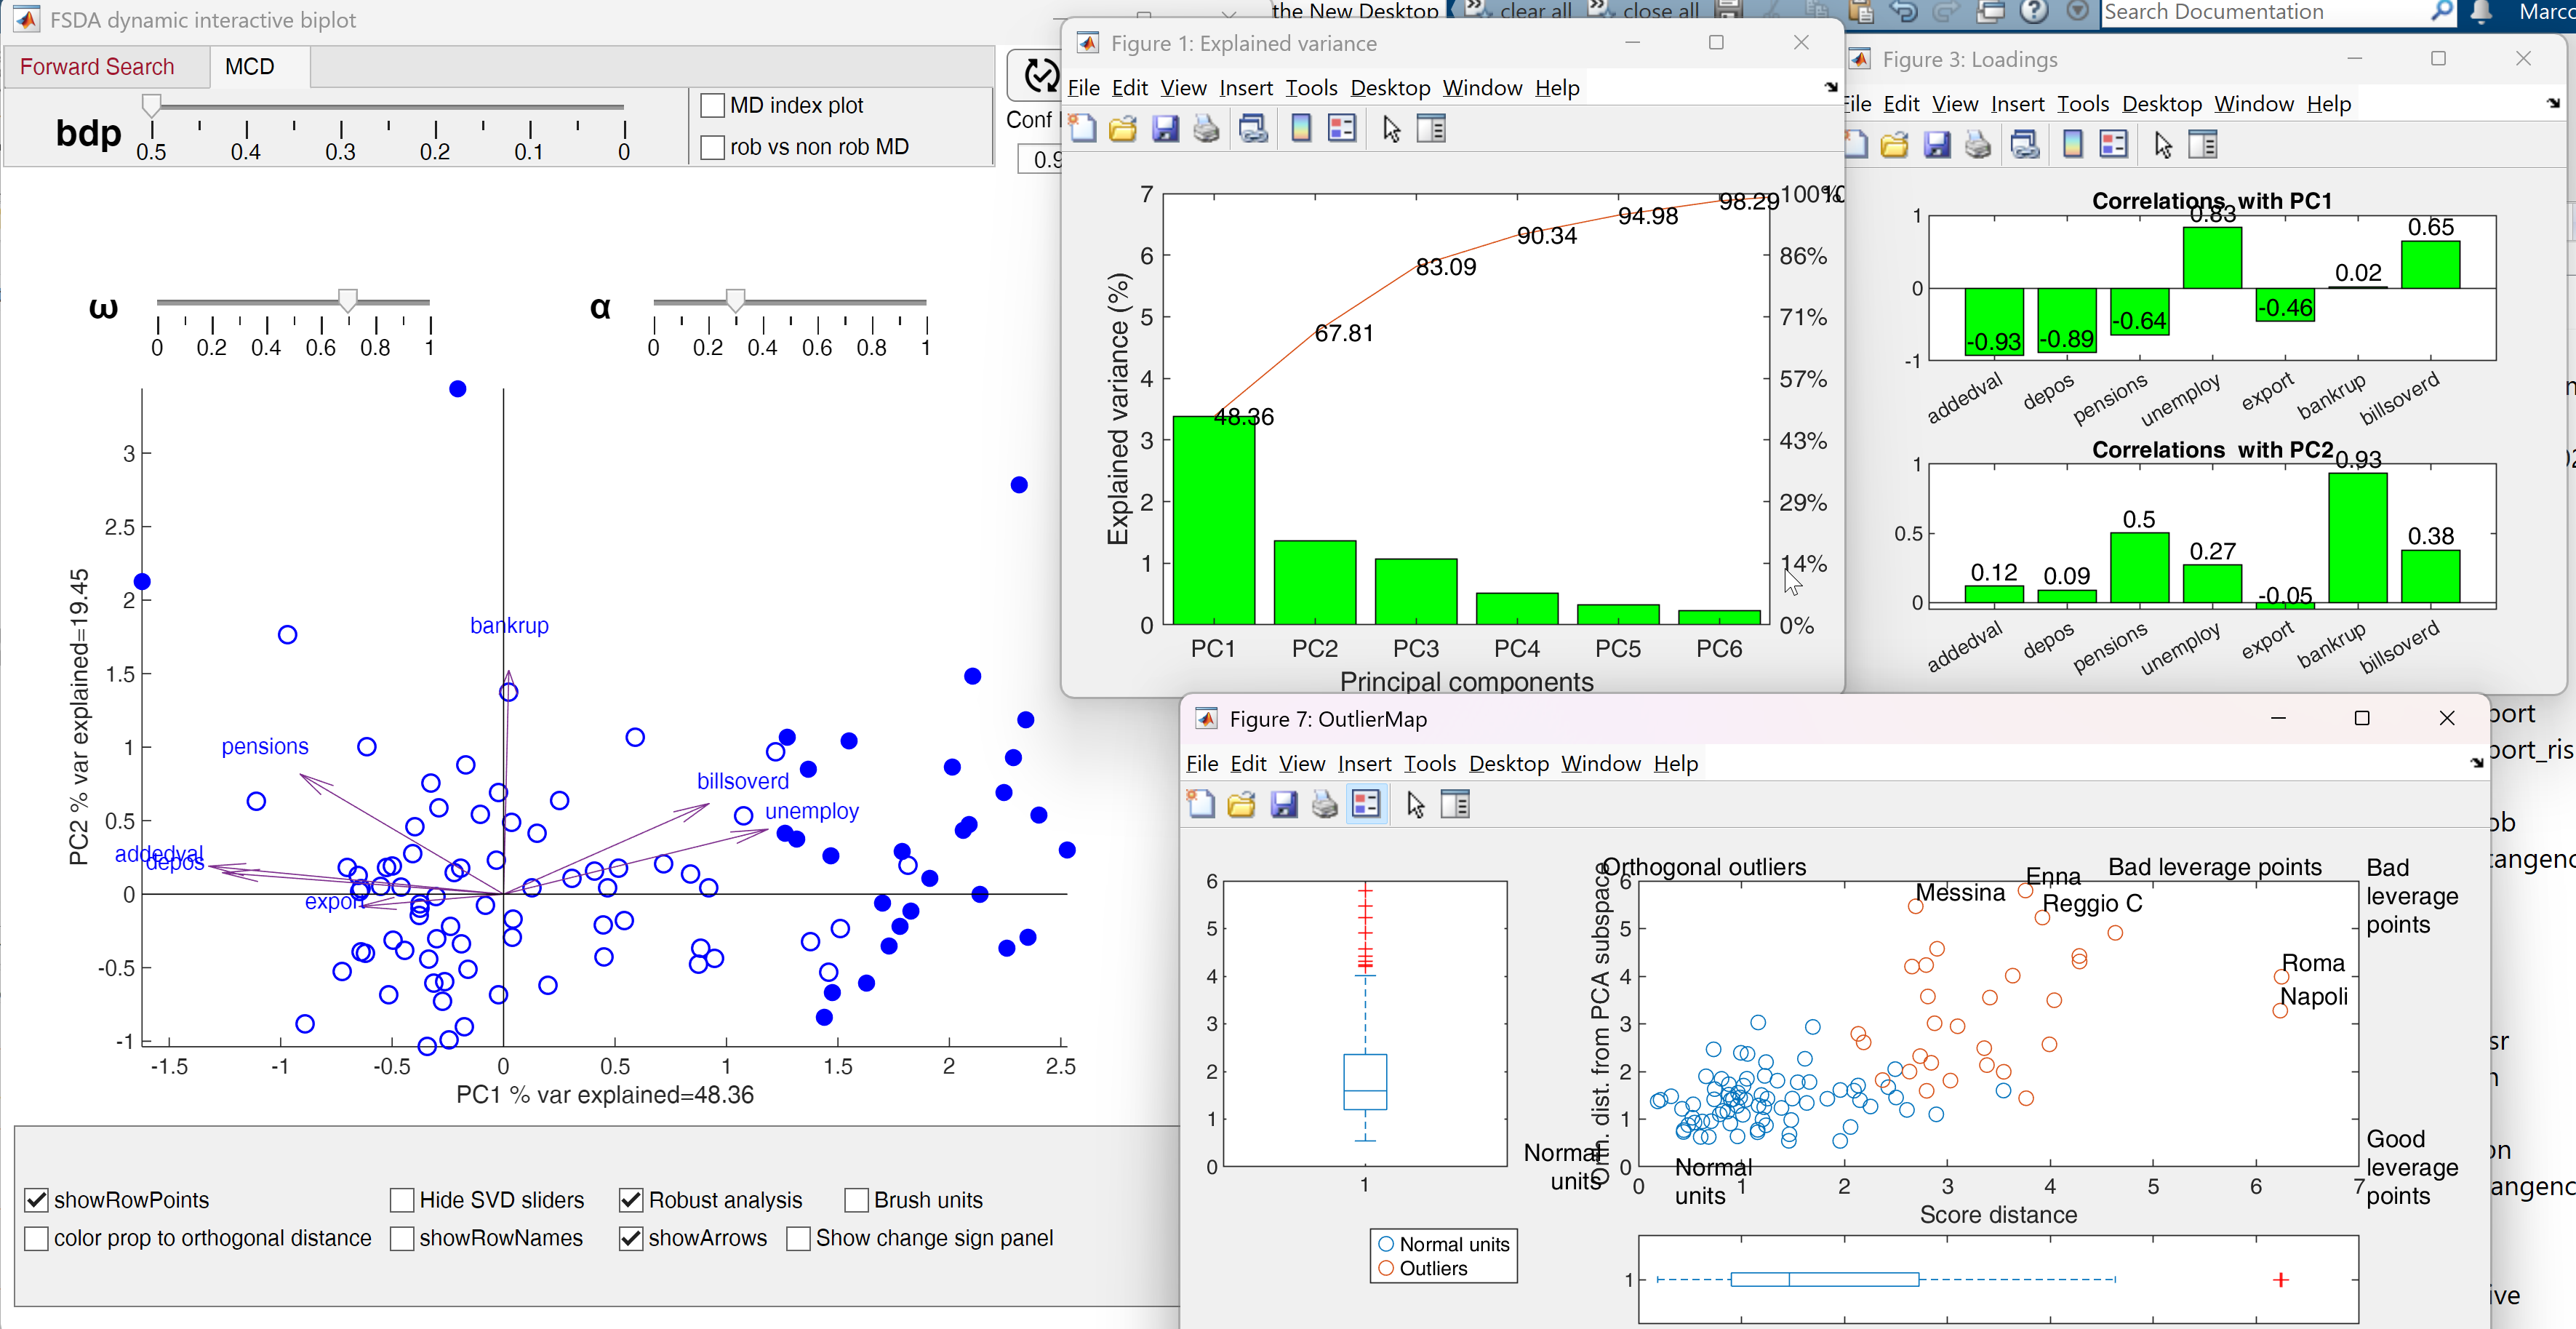

References

Atkinson, A. C. and Riani, M. and Corbellini, A. and Perrotta, D. and Todorov, V. (2025), [*Applied Robust Statistics through the Monitoring Approach, Applications in Regression*](https://link.springer.com/book/9783031883644)*, *Heidelberg: Springer Nature.  [https://github.com/UniprJRC/MonitoringBook](https://github.com/UniprJRC/MonitoringBook) 

[](https://github.com/UniprJRC/MonitoringBook)